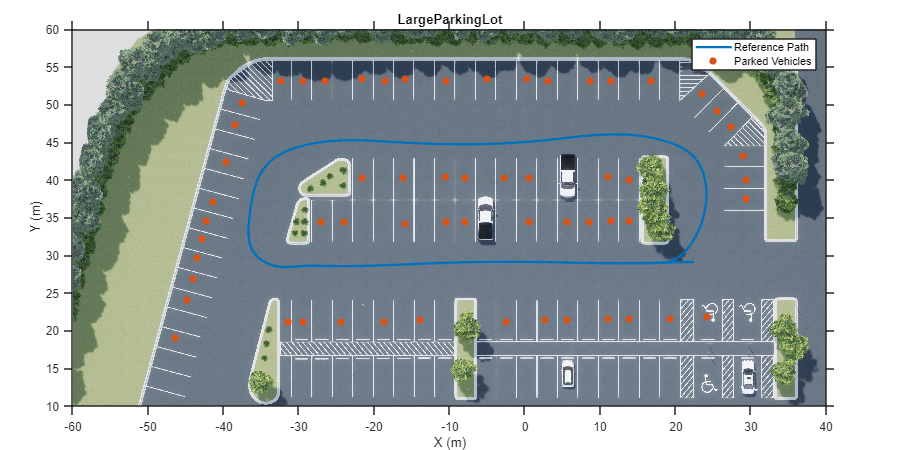

% Load reference path
data = load("parkingLotReferenceData.mat");

% Set reference trajectory of the ego vehicle
refPosesX = data.refPosesX;
refPosesY = data.refPosesY;
refPosesT = data.refPosesT;

% Set poses of the parked vehicles
parkedPoses = data.parkedPoses;

% Display the reference path and the parked vehicle locations
sceneName = "LargeParkingLot";
hScene = figure;
helperShowSceneImage(sceneName);
hold on
plot(refPosesX(:,2), refPosesY(:,2), LineWidth=2, DisplayName='Reference Path');
scatter(parkedPoses(:,1), parkedPoses(:,2), [], 'filled', DisplayName='Parked Vehicles');
xlim([-60 40])
ylim([10 60])
hScene.Position = [100, 100, 1000, 500]; % Resize figure
legend
hold off

Open the model and add parked vehicles

modelName = 'GenerateImageDataOfParkingLot';
open_system(modelName);

helperAddParkedVehicles(modelName, parkedPoses);

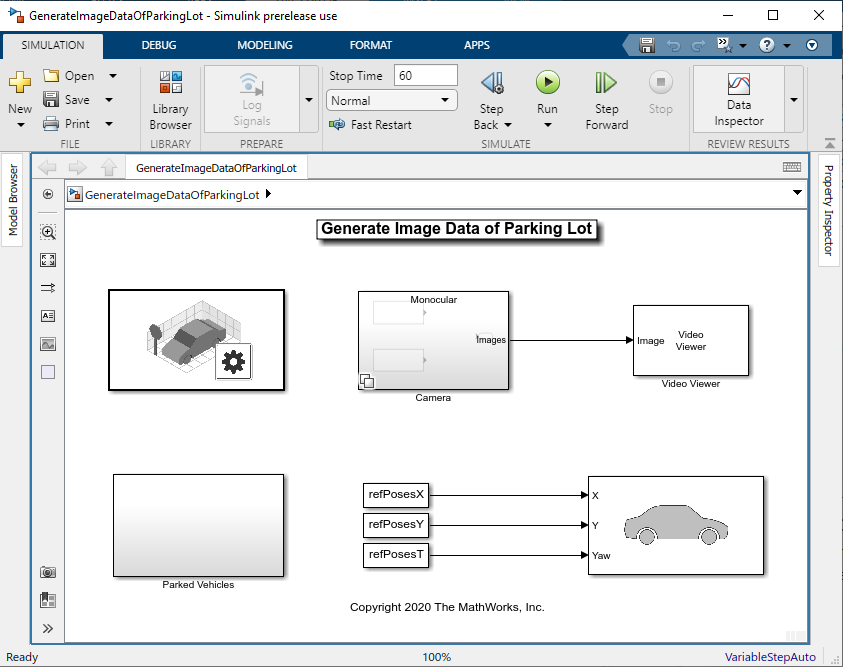

## Set Up Ego Vehicle and Camera Sensor

% Select monocular camera
useMonoCamera = 1;

% Inspect the monocular camera
open_system([modelName, '/Camera/Monocular']);

% Camera intrinsics
focalLength    = [700, 700];  % specified in units of pixels
principalPoint = [600, 180];  % in pixels [x, y]
imageSize      = [370, 1230]; % in pixels [mrows, ncols]
intrinsics     = cameraIntrinsics(focalLength, principalPoint, imageSize);

## Visualize and Record Sensor Data

Run the simulation to visualize and record sensor data. Use the Video Viewer block to visualize the image output from the camera sensor. Use the To Workspace block to record the ground truth location and orientation of the camera sensor. 

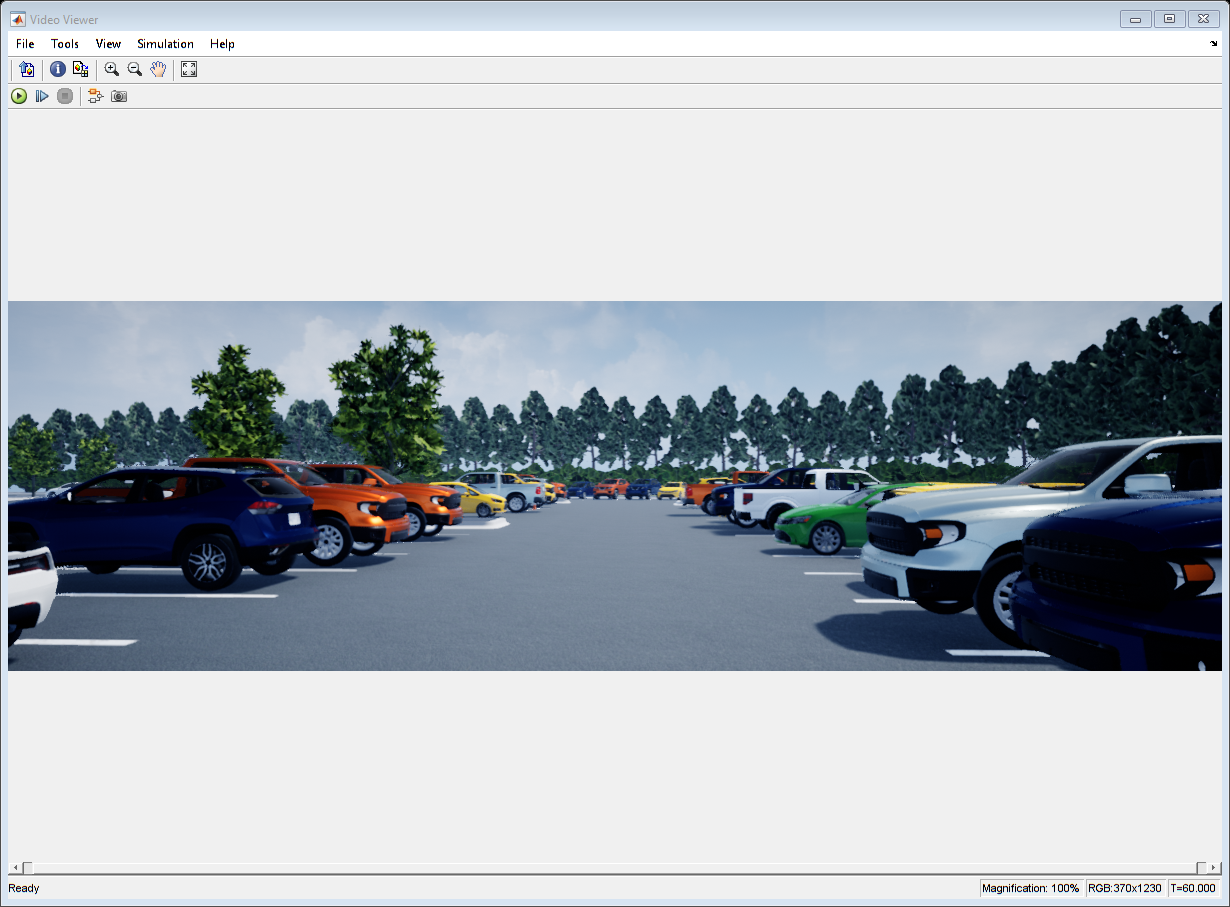

close(hScene)

if ~ispc
    error("Unreal Engine Simulation is supported only on Microsoft" + char(174) + " Windows" + char(174) + ".");
end

% Run simulation
simOut = sim(modelName);


% Extract camera images as an imageDatastore
imds = helperGetCameraImages(simOut);

% Extract ground truth as an array of rigidtform3d objects
gTruth = helperGetSensorGroundTruth(simOut);

## Develop Monocular Visual SLAM Algorithm Using Recorded Data

- **Map Initialization**: ORB-SLAM starts by initializing the map of 3-D points from two images. Use [`estrelpose`](docid:vision_ref#mw_839e96cc-f499-4cbb-8c26-4df25c958dc9) to compute the relative pose based on 2-D ORB feature correspondences and [`triangulate`](docid:vision_ref#buefm11-1) to compute the 3-D map points. The two frames are stored in an [`imageviewset`](docid:vision_ref#mw_6e9e9e26-1c92-4289-a7d9-bccafaf79b78) object as key frames. The 3-D map points and their correspondences to the key frames are stored in a `worldpointset` object.

- **Tracking**: Once a map is initialized, for each new image, the function `helperTrackLastKeyFrame` estimates the camera pose by matching features in the current frame to features in the last key frame. The function `helperTrackLocalMap` refines the estimated camera pose by tracking the local map.

- **Local Mapping**: The current frame is used to create new 3-D map points if it is identified as a key frame. At this stage, [`bundleAdjustment`](docid:vision_ref#bu48f97-1) is used to minimize reprojection errors by adjusting the camera pose and 3-D points.

- **Loop Closure**: Loops are detected for each key frame by comparing it against all previous key frames using the bag-of-features approach. Once a loop closure is detected, the pose graph is optimized to refine the camera poses of all the key frames using the [`optimizePoseGraph`](docid:nav_ref#mw_ead0d07b-dffc-4389-93ef-8fa1432c60cb) function.

Map initialized with frame 1 and frame 11


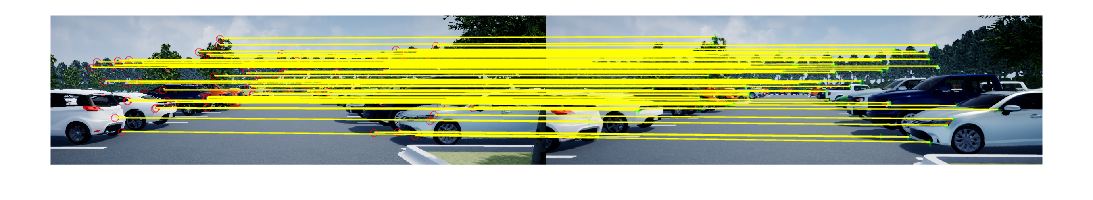

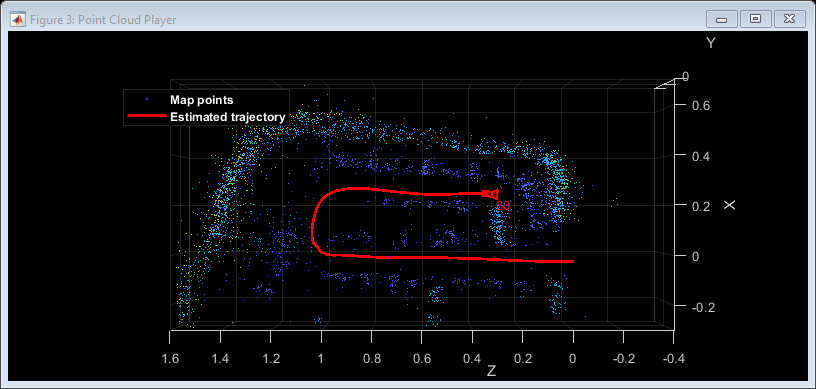

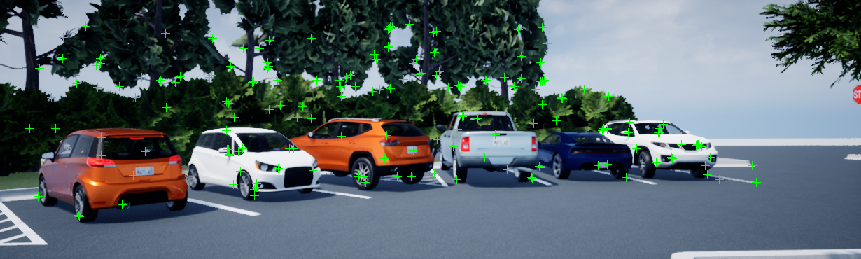

Loop closure cannot be found


[mapPlot, optimizedPoses, addedFramesIdx] = helperVisualSLAM(imds, intrinsics); 

## Stereo Visual SLAM Algorithm

% Select stereo camera
useMonoCamera = 0;

% Inspect the stereo camera
open_system([modelName, '/Camera/Stereo']);
snapnow;

% Set stereo camera baseline
baseline = 0.5; % In meters

% Construct the reprojection matrix for 3-D reconstruction
reprojectionMatrix = [1, 0, 0, -principalPoint(1); 
    0, 1, 0, -principalPoint(2);
    0, 0, 0, focalLength(1);
    0, 0, 1/baseline, 0];

% Maximum disparity in stereo images
maxDisparity = 48;

% Run simulation
simOut = sim(modelName);
snapnow;

## Extract Stereo Images

[imdsLeft, imdsRight] = helperGetCameraImagesStereo(simOut);

% Extract ground truth as an array of rigidtform3d objects
gTruth = helperGetSensorGroundTruth(simOut);

Run the stereo visual SLAM algorithm

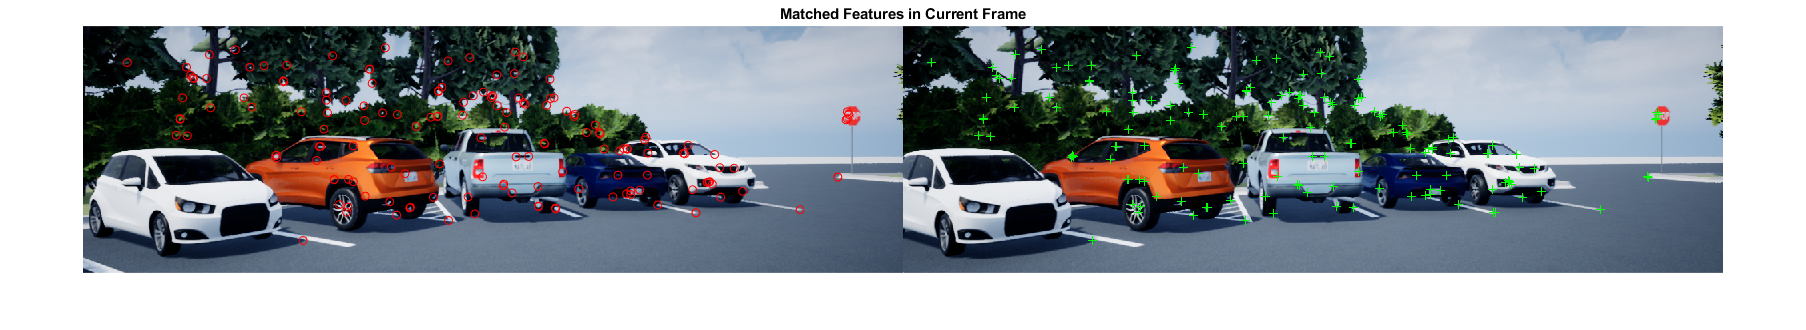

Loop closure cannot be found


[mapPlot, optimizedPoses, addedFramesIdx] = helperVisualSLAMStereo(imdsLeft, imdsRight, intrinsics, maxDisparity, reprojectionMatrix);

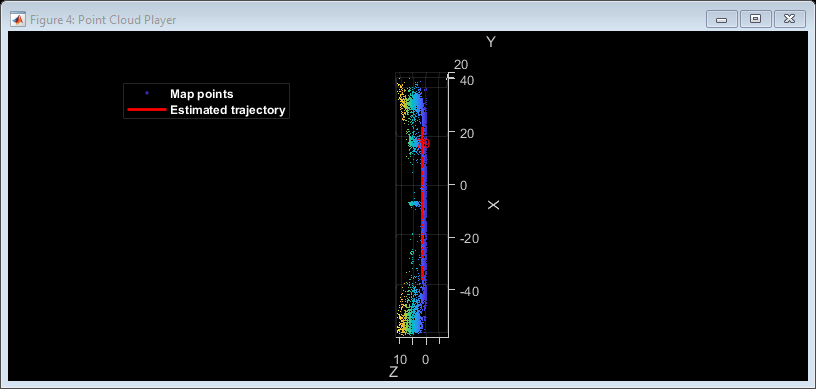

% Plot the camera ground truth trajectory
optimizedTrajectory = plotActualTrajectory(mapPlot, gTruth(addedFramesIdx));


% Show legend
showLegend(mapPlot);

% Calculate the root mean square error (RMSE) of trajectory estimates
helperEstimateTrajectoryError(gTruth(addedFramesIdx), optimizedTrajectory);

Compared with the monocular visual SLAM algorithm, the stereo visual SLAM algorithm produces a more accurate estimation of the camera trajectory.

## Dense Reconstruction from Stereo Images

Given the refined camera poses, you can perform dense reconstruction from the stereo images corresponding to the key frames. 

pointCloudsAll = helperDenseReconstructFromStereo(imdsLeft, imdsRight, ...
    imageSize, addedFramesIdx, optimizedPoses, maxDisparity, reprojectionMatrix);

% Visualize the scene
figure(Position=[1100 600 1000 500]);
ax = pcshow(pointCloudsAll,VerticalAxis="y", VerticalAxisDir="down");
xlabel('X')
ylabel('Y')
zlabel('Z')

% Display bird's eye view of the parking lot
view(ax, [0 -1 0]);
camroll(ax, 90);

close_system(modelName, 0);

close all

## Supporting Functions

**helperGetCameraImages** Get camera output 

function imds = helperGetCameraImages(simOut)
% Save image data to a temporary folder
dataFolder   = fullfile(tempdir, 'parkingLotImages', filesep); 
folderExists = exist(dataFolder, 'dir');
if ~folderExists  
    mkdir(dataFolder);
end

files = dir(dataFolder);
if numel(files) < 3
    numFrames = numel(simOut.images.Time);
    for i = 3:numFrames % Ignore the first two frames
        img = squeeze(simOut.images.Data(:,:,:,i));
        imwrite(img, [dataFolder, sprintf('%04d', i-2), '.png'])
    end
end

% Create an imageDatastore object to store all the images
imds = imageDatastore(dataFolder);
end

**helperGetCameraImagesStereo** Get camera output 

function [imdsLeft, imdsRight] = helperGetCameraImagesStereo(simOut)
% Save image data to a temporary folder
dataFolderLeft   = fullfile(tempdir, 'parkingLotStereoImages', filesep, 'left', filesep);
dataFolderRight  = fullfile(tempdir, 'parkingLotStereoImages', filesep, 'right', filesep);
folderExists     = exist(dataFolderLeft, 'dir');
if ~folderExists  
    mkdir(dataFolderLeft);
    mkdir(dataFolderRight);
end

files = dir(dataFolderLeft);
if numel(files) < 3
    numFrames = numel(simOut.imagesLeft.Time);
    for i = 3:numFrames % Ignore the first two frames
        imgLeft = squeeze(simOut.imagesLeft.Data(:,:,:,i));
        imwrite(imgLeft, [dataFolderLeft, sprintf('%04d', i-2), '.png'])
        
        imgRight = squeeze(simOut.imagesRight.Data(:,:,:,i));
        imwrite(imgRight, [dataFolderRight, sprintf('%04d', i-2), '.png'])
    end
end

% Use imageDatastore objects to store the stereo images
imdsLeft  = imageDatastore(dataFolderLeft);
imdsRight = imageDatastore(dataFolderRight);
end

**helperGetSensorGroundTruth** Save the sensor ground truth

function gTruth = helperGetSensorGroundTruth(simOut)
numFrames = numel(simOut.location.Time);
gTruth = repmat(rigidtform3d, numFrames-2, 1);
for i = 1:numFrames-2 % Ignore the first two frames
    gTruth(i).Translation = squeeze(simOut.location.Data(:, :, i+2));
    % Ignore the roll and the pitch rotations since the ground is flat
    yaw = double(simOut.orientation.Data(:, 3, i+2));
    gTruth(i).R = [cos(yaw), -sin(yaw), 0; ...
        sin(yaw), cos(yaw), 0; ...
        0, 0, 1];
end
end

**helperEstimateTrajectoryError** Calculate the tracking error

function rmse = helperEstimateTrajectoryError(gTruth, scaledLocations)
gLocations      = vertcat(gTruth.Translation);

rmse = sqrt(mean( sum((scaledLocations - gLocations).^2, 2) ));
disp(['Absolute RMSE for key frame trajectory (m): ', num2str(rmse)]);
end

**helperDenseReconstructFromStereo** Perform dense reconstruction from stereo images with known camera poses

function pointCloudsAll = helperDenseReconstructFromStereo(imdsLeft, imdsRight, ...
    imageSize, addedFramesIdx, optimizedPoses, maxDisparity, reprojectionMatrix)

ptClouds =  repmat(pointCloud(zeros(1, 3)), numel(addedFramesIdx), 1);

for i = 1: numel(addedFramesIdx)
    I1 = readimage(imdsLeft, addedFramesIdx(i));
    I2 = readimage(imdsRight, addedFramesIdx(i));
    disparityMap = disparitySGM(im2gray(I1), im2gray(I2), DisparityRange=[0, maxDisparity],UniquenessThreshold=20);
    xyzPoints  = reconstructScene(disparityMap, reprojectionMatrix);
    
    % Ignore the upper half of the images which mainly show the sky
    xyzPoints(1:100, :, :) = NaN;
    
    xyzPoints  = reshape(xyzPoints, [imageSize(1)*imageSize(2), 3]);

    validIndex = xyzPoints(:, 3) > 0 & xyzPoints(:, 3) < 40/reprojectionMatrix(4, 3);
    
    xyzPoints  = xyzPoints(validIndex, :);
    colors = reshape(I1, [imageSize(1)*imageSize(2), 3]);
    colors = colors(validIndex, :);

    currPose = optimizedPoses.AbsolutePose(i);
    xyzPoints  = transformPointsForward(currPose, xyzPoints); 
    ptCloud = pointCloud(xyzPoints, Color=colors);
    ptClouds(i) = pcdownsample(ptCloud, random=0.2); 
end

% Concatenate the point clouds
pointCloudsAll = pccat(ptClouds);
end